fire1写入视频.


fire2写入视频.


fire3写入视频.


fire4写入视频.


fire5写入视频.


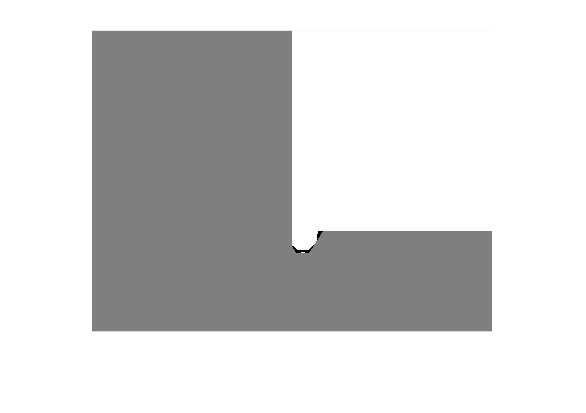

%%
%
% <<FILENAME.PNG>>
%

clc;
clear all;
num=5;


if 1
    
    vedio = VideoWriter('../data/videos/demo.avi'); %初始化一个avi文件
    vedio.FrameRate = 50;
    open(vedio);
    
    
    for i=1:num
        image=load(strcat('../data/trans_txt/',int2str(i),'.txt'));
        
        image=uint8(image);
        imshow(image);
        imwrite(image,strcat('../data/trans_png/',int2str(i),'.png'));
        writeVideo(vedio,image);
        disp(strcat('fire',int2str(i),'写入视频.'));
    end
    close(vedio);
    
end


if 0
    for i=1:num
        
        image=imread(strcat('../data/fire6/fire',int2str(i),'.bmp'));
        image=~image;
        
        image_txt=strcat('../data/m2c/m2c',int2str(i),'.txt');%为 txt 文件去名字
        fid=fopen(image_txt,'w');
        fprintf(fid,'%d ',image);
        fclose(fid);
        
        %imwrite(image,strcat('fire',int2str(i),'.jpg'));
        disp(strcat('fire',int2str(i),'转换结束.'));
        
        
    end
    disp('批量转换结束.');
    
    
    
    
    

   
    
    %以下为转换成视频的代码
    
    
    if 0
        vedio = VideoWriter('demo3.avi'); %初始化一个avi文件
        vedio.FrameRate = 50;
        open(vedio);
        for i=1:num %图像序列个数
            fname=strcat('fire',num2str(i,'%d'),'.jpg');
            frame = imread(fname);
            
            writeVideo(vedio,frame);
            disp(strcat('fire',int2str(i),'写入视频.'));
            
        end
        close(vedio);
    end
end




%一下为图像处理后的视频合成
if 0
    vedio = VideoWriter('../data/videos/demo.avi'); %初始化一个avi文件
    vedio.FrameRate = 50;
    open(vedio);
    
    for i=1:num

        image=load(strcat('../data/c2m/c2m',int2str(i),'.txt'));
        image=uint8(image);
        %imshow(image);
        imwrite(image,strcat('../data/jpg/',int2str(i),'.png'));
        %     fname=strcat('../data/jpg/',num2str(i,'%d'),'.png');
        %     frame = imread(fname);
        writeVideo(vedio,image);
        disp(strcat('fire',int2str(i),'写入视频.'));
    end
    close(vedio);
end

